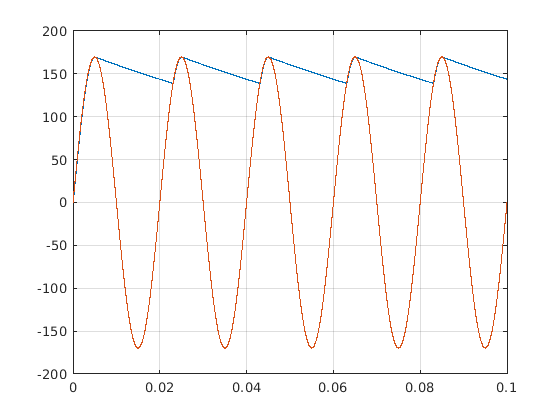

clc; clear all; close all;

R = 1500; % Ohm
C = 60*10^-6; % Farad

U = 120; % V
f = 50; % Hz

R_D1 = 1; % Ohm

uC = 0; % V

t = 0; % s
dt = 10^-5; % Timestep
idx = 1; % Counter

simTime = 0.1; % s

while t <= simTime

    % Supply Voltage
    uA = U*sqrt(2)*sin(2*pi*f*t);

    % Current going through diode
    if(uA <= uC)
        i1 = 0;
    elseif(uA > uC)
        i1 = (uA-uC)/R_D1;
    end

    % Current going through resistor
    i3 = uC/R;

    % Current going through condensator
    i2 = i1 - i3;

    % Change in voltage over the capacitor
    uCDot = (1/C) * i2;

    t_plot(idx) = t;
    uCPlot(idx) = uC;
    uAPlot(idx) = uA;

    % Time Integration
    uC = uC + uCDot * dt;

    t = t + dt;
    idx = idx + 1;

end

plot(t_plot, uCPlot)
hold on
plot(t_plot, uAPlot)
grid